# Exercise 4

This is a 4 dof robot, with 4 rotoidal joints (this are orthogonal or parallel so we can define the robot with DH or ...). The objective is to calculatate the position of the joint variables using the inverse kinematics.

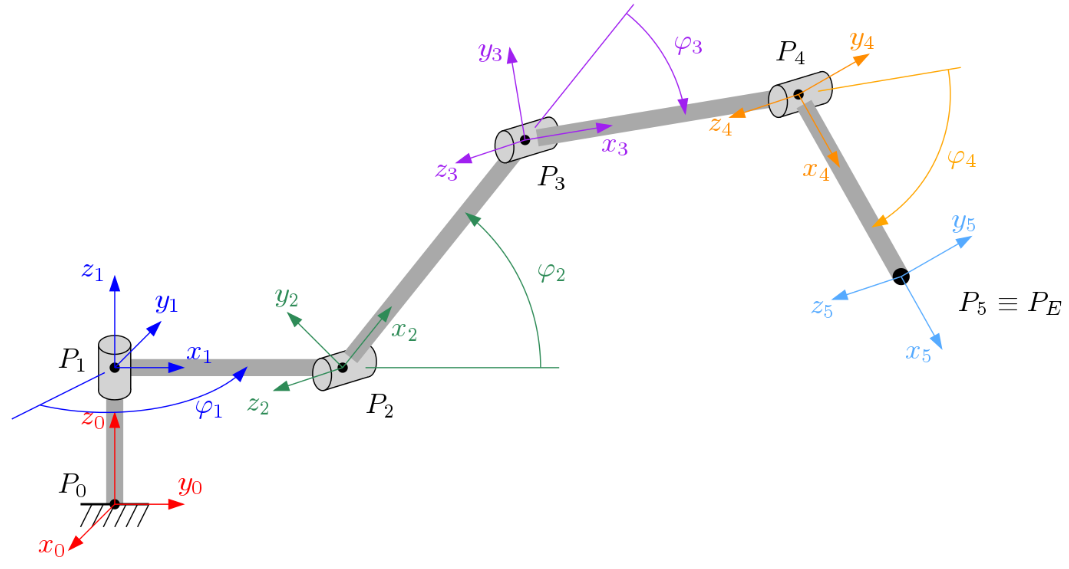

I'll use the following DH convention:

  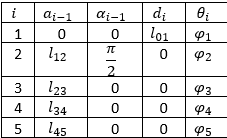


$$T_i^{i-1} =

\pmatrix{\cos(\theta_i) & -\sin(\theta_i) & 0 & a_{i-1} \cr \sin(\theta_i)\cos(\alpha_{i-1}) & \cos(\theta_i)\cos(\alpha_{i-1}) & -\sin(\alpha_{i-1}) & -\sin(\alpha_{i-1})d_i \cr \sin(\theta_i)\sin(\alpha_{i-1}) & \cos(\theta_i)\sin(\alpha_{i-1}) & \cos(\alpha_{i-1}) & \cos(\alpha_{i-1})d_i \cr 0 & 0 & 0 & 1}$$


import plotFrame.*;

clear all;

l01 = 2;
l12 = 2;
l23 = 2;
l34 = 2;
l45 = 2;

P5 = [3 3 4]'; %% this is the position of the end-effector in the global frame

theta = -pi/4; %% orientation of link 4 w.r.t global frame

phi1 = atan2(P5(2), P5(1));

H10 = DHMatrix(0, 0, l01, phi1);
H21 = DHMatrix(l12, pi/2, 0, 0); %% this is just the translation because IDK the phi2 angle right now

l45proj = l45*cos(theta);
xproj = l45proj*cos(phi1);
yproj = l45proj*sin(phi1);
zproj = l45*sin(theta);

P4 = [P5(1) - xproj;
     P5(2) - yproj;
     P5(3) - zproj;
     1
    ];        %% first we find P4

norm([P5; 1] - P4) % checking that the distance between P5 and P4 is exactly l45

ans = 2

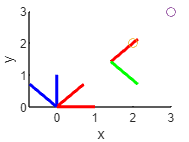

% display of the 3 initial reference frames and P4 and P5
clf;
hold on;
plotFrame(eye(4));
plotFrame(eye(4)*H10);
plotFrame(eye(4)*H10*H21);
plot3(P4(1), P4(2), P4(3), '-o');
plot3(P5(1), P5(2), P5(3), '-o');
xlabel('x');
ylabel('y');
zlabel('z');

% caculation of the elbow down solution of the inverse kinematics

newP4 = inv(H10*H21)*P4;
newP4 = newP4(1:2);
r = norm(newP4);

c1 = (l23^2 + l34^2 - r^2)/(2*l23*l34);
c2 = (r^2 + l23^2 - l34^2)/(2*l23*r);

gamma = acos(c1);
alpha = acos(c2);

phi3 = pi - gamma;
phi2 = atan2(newP4(2), newP4(1)) - alpha;
phi4 = theta - phi2 - phi3;

rad2deg(phi2)

ans = 47.8017

rad2deg(phi3)

ans = 57.1192

rad2deg(phi4)

ans = -149.9209

% Calculation of the transformation matrices from the DH-table using the
% reference frame proposed above

H10 = DHMatrix(0, 0, l01, phi1);
H21 = DHMatrix(l12, pi/2, 0, phi2);
H32 = DHMatrix(l23, 0, 0, phi3);
H43 = DHMatrix(l34, 0, 0, phi4);
H54 = DHMatrix(l45, 0, 0, 0);

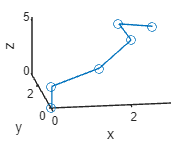

% Display the robot
clf;

fP0 = [0 0 0 1]';
fP1 = H10*fP0;
fP2 = H10*H21*fP0;
fP3 = H10*H21*H32*fP0;
fP4 = H10*H21*H32*H43*fP0;
fP5 = H10*H21*H32*H43*H54*fP0;

points = [fP0 fP1 fP2 fP3 fP4 fP5];

hold on;
plot3(points(1, :), points(2, :), points(3, :), '-o');
view([-9 30]);
xlabel('x');
ylabel('y');
zlabel('z');

% checking the distances between each point match the Lxy
norm(fP5-fP4)

ans = 2

norm(fP4-fP3)

ans = 2.0000

norm(fP3-fP2)

ans = 2.0000

norm(fP2-fP1)

ans = 2

norm(fP1-fP0)

ans = 2

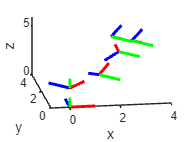

% plotting the reference frames
clf;
hold on;
plotFrame(eye(4));
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);
plotFrame(H10*H21*H32*H43);
plotFrame(H10*H21*H32*H43*H54);
view([-9 30]);
xlabel('x');
ylabel('y');
zlabel('z');

function matrix = DHMatrix(a, alpha, d, theta)
    % function to create the matrix from the DH table row
    matrix = [cos(theta) -sin(theta) 0 a;
              sin(theta)*cos(alpha) cos(theta)*cos(alpha) -sin(alpha) -sin(alpha)*d;
              sin(theta)*sin(alpha) cos(theta)*sin(alpha) cos(alpha) cos(alpha)*d;
              0 0 0 1
             ];
end